# Debugging C/C++ code in Simulink

As you probably know, it is possible to integrate C/C++ code in Simulink simulations. This can be done in many ways, including:

- C/C++ S-Function

- S-Function Builder

- Legacy Code Tool

- C Caller

- C Function

- MATLAB Function

- MATLAB System

- Stateflow chart

A long time ago, I published a blog post describing [how to debug C/C++ S-Functions](https://blogs.mathworks.com/simulink/2012/12/06/debugging-cc-s-functions). At that time, the process was complex and required you to manually mex the S-Function with debug flags and attach the debugger to the MATLAB process.

In recent releases, we have greatly simplified the process. In this post, I will highlight how this can be done in two ways:

- Using [Microsoft Visual Studio compiler and IDE](https://www.mathworks.com/matlabcentral/answers/443349-how-do-i-install-visual-studio-for-use-with-matlab-simulink)

- Using [MinGW](https://www.mathworks.com/matlabcentral/fileexchange/52848-matlab-support-for-mingw-w64-c-c-compiler), [GDB](https://www.sourceware.org/gdb/), and [Visual Studio Code](https://code.visualstudio.com/)

## Initial Setup

If you plan to use this feature, I recommend to first go through this documentation page: [Debug Custom C/C++ Code](https://www.mathworks.com/help/releases/R2023a/simulink/ug/debug-custom-code.html)

This page lists the supported blocks along with the compilers and IDEs supported for different operating systems.

On Windows, to use the Microsoft Visual Studio debugger, you will likely need to set a Windows registry key. You can see if this registry key entry is already configured by executing this line of code:

If this key does not exist or is set to a lower number than 4096, follow the documentation instructions to configure it.

## Set Breakpoints in Custom Code

To illustrate this process, I used those simple C file and header:

edit myFunc.c
edit myFunc.h

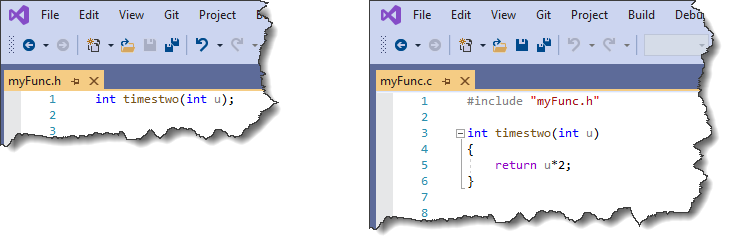

I created a new model and specified the C file in its configuration:

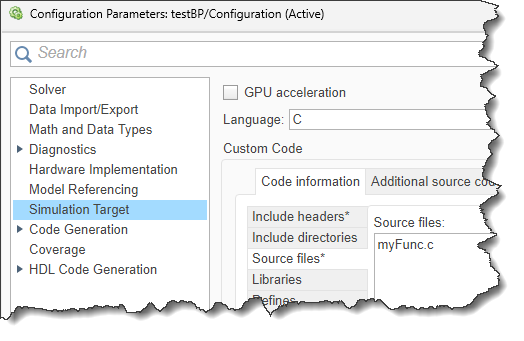

I then switched to the `Include headers` section and used the `Auto-fill from source files` button to automatically fill the include headers text:

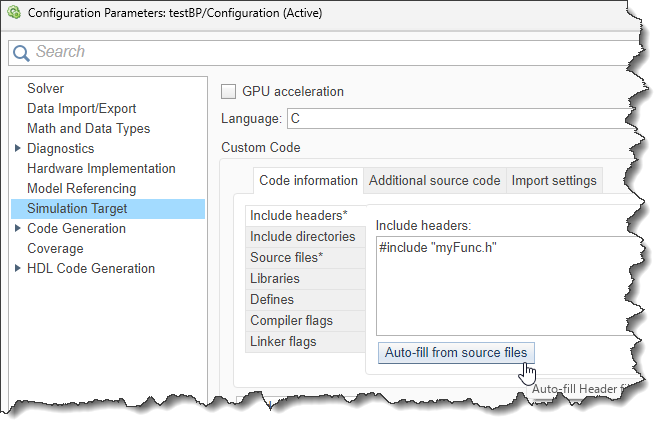

I added a [C Caller](https://www.mathworks.com/help/releases/R2023a/simulink/slref/ccaller.html) block to the model and could select my function in its dialog:

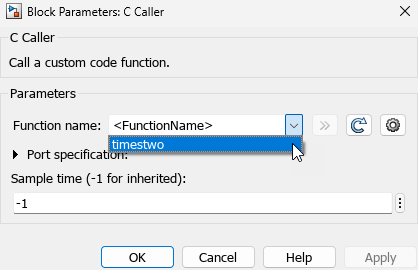

I connected inputs and outputs to the C Caller block to have a working simulation:

open_system('testBP')

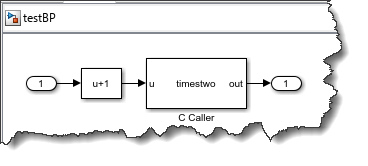

In the Debug tab, I can then click on **Set Breakpoints in Custom Code**:

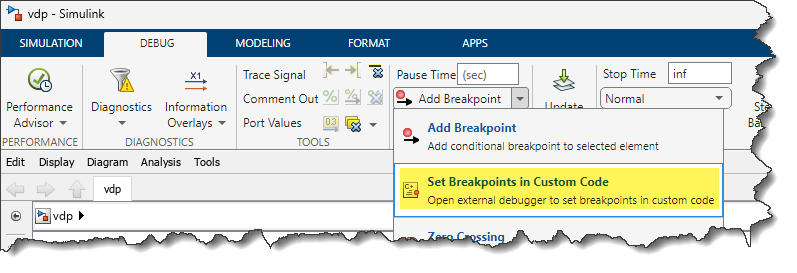

The model status bar will tell us that it is launching the external debugger

Microsoft Visual Studio will open the C file and automatically attach to the MATLAB process. At this point, you can set breakpoints in the custom code, click play in Simulink, and inspect the C code when the breakpoints is hit:  

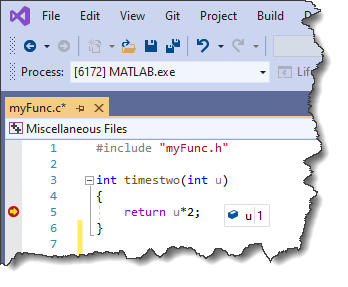

## MinGW and Visual Studio Code

If you prefer to use MinGW, GDB and Visual Studio Code, you will need to install the [MATLAB® Coder™ Interface for Visual Studio Code Debugging](https://www.mathworks.com/matlabcentral/fileexchange/103555-matlab-coder-interface-for-visual-studio-code-debugging) support package. Once the installation is complete, execute this line of code to install the extension in Visual Studio Code:

Debugging custom code in Visual Studio Code is only supported when the custom code is [simulated in a separate process](https://www.mathworks.com/help/releases/R2023a/simulink/gui/simulate-custom-code-in-a-separate-process.html). This means that you will need to enable this option:

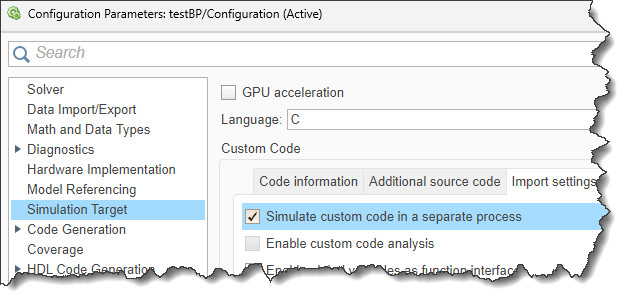

Once this is done, the process is similar to the one described above with Visual Studio. Click the **Set Breakpoints in Custom Code **button in the Debug tab of the toolstrip, this will launch Visual Studio Code and attach it to the MATLAB process. Add the breakpoints in the code and simulate the model.

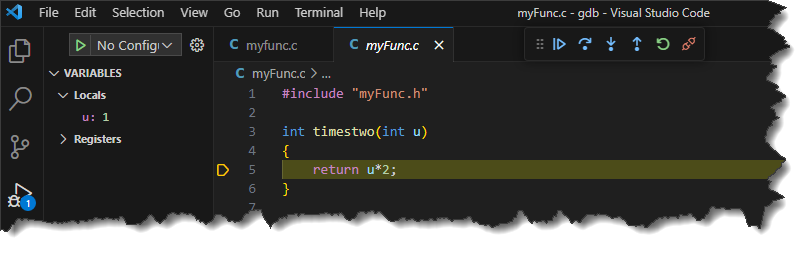

## Now it's your Turn

Are you leveraging this feature to set breakpoints and debug your custom C code? Do you prefer to use Visual Studio or Visual Studio Code to debug your C code?

[ ](http://matlab.mathworks.com/open/github/v1?repo=https://github.com/simulink/blog&file=custom_code_breakpoints.mlx)